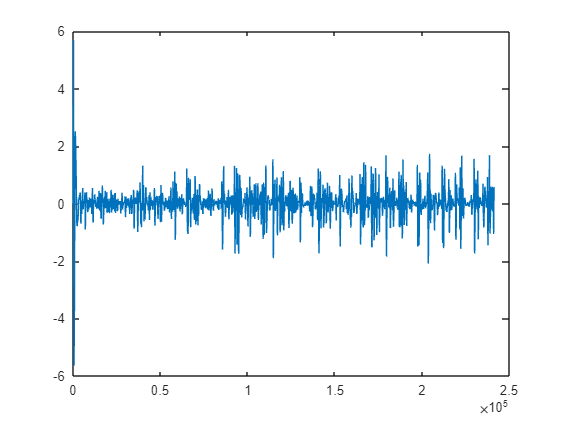

File 26 telah ditulis ke Excel.


fname1 ='BitalinoGSR.txt';
fname2 = 'Triggers.txt';
fld ='Dataset';
count = 0;

% Nama file Excel yang akan dibuat
result_file = 'GSR_Features3.xlsx';

% Inisialisasi header (nama kolom)
% Nama-nama variabel fitur GSR
headers = {
    'Subjek', ...
    'Clip', ...
    'Label', ...
    'SCL_Mean', ...
    'SCL_STD', ...
    'SCL_Skewness', ...
    'SCL_Kurtosis', ...
    'SCR_Number', ...
    'SCR_Amplitude_Mean', ...
    'SCR_Amplitude_STD', ...
    'SCR_Amplitude_Max', ...
    'SCR_Amplitude_Min', ...
    'SCR_Duration_Mean', ...
    'SCR_Duration_STD', ...
    'SCR_Duration_Max', ...
    'SCR_Duration_Min', ...
    'SCR_Frequency', ...
    'SCL_Variance', ...
    'SCL_Slope', ...
    'GSR_Mean', ...
    'GSR_STD', ...
    'GSR_Skewness', ...
    'GSR_Kurtosis', ...
    'GSR_Max', ...
    'GSR_Min', ...
    'Power_VLF', ...
    'Power_LF', ...
    'Power_HF', ...
    'LF_HF_Ratio', ...
    'GSR_Trend_Slope'
};


% Tulis header ke file Excel (menulis di sel A1:J1)
writecell(headers, result_file, 'Sheet', 1, 'Range', 'A1');

% Tentukan jumlah baris data yang akan diproses
numRows = 10000000;  % Sesuaikan dengan kebutuhan Anda

for num = 26:26
    %Import file ECG dan Trigger
    GSRfilename = ['C:\Users\kayyi\Downloads\Preprocessing Dataset\Dataset\','VP',num2str(num),'\',fname1];
    if exist (GSRfilename, 'file') == 0
        %file does not exist
        continue;
    end

    Triggerfilename = ['C:\Users\kayyi\Downloads\Preprocessing Dataset\Dataset\','VP',num2str(num),'\',fname2];

    trig = importTrigger(Triggerfilename);
    gsr = importECG(GSRfilename);

    %Split Data
    row_gsr = size(gsr,1);
    col_gsr = size(gsr,2);
    row_trig = size(trig,1);
    col_trig = size(trig,2);
    
    baseline = zeros(1,1);
    demo = zeros(1,1);
    clip1 = zeros(1,1);
    clip2 = zeros(1,1);
    clip3 = zeros(1,1);
    clip4 = zeros(1,1);
    clip5 = zeros(1,1);
    clip6 = zeros(1,1);
    clip7 = zeros(1,1);
    clip8 = zeros(1,1);
    clip9 = zeros(1,1);
    clip10 = zeros(1,1);
    clip11 = zeros(1,1);
    clip12 = zeros(1,1);
    clip13 = zeros(1,1);
    clip14 = zeros(1,1);
    clip15 = zeros(1,1);
    clip16 = zeros(1,1);
    rest_1 = zeros(1,1);
    rest_2 = zeros(1,1);
    rest_3 = zeros(1,1);
    rest_4 = zeros(1,1);
    rest_5 = zeros(1,1);
    
    %Baseline
    for i=1:row_gsr
        if gsr(i,2) < trig(1,1)
            baseline(i,1) = gsr(i,1);
    
        end
    end
    
    
    %Clip-Demo
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(1,1)) && (gsr(i,2) < trig(1,2))
            demo(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip1
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(2,1)) && (gsr(i,2) < trig(2,2))
            clip1(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip2
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(3,1)) && (gsr(i,2) < trig(3,2))
            clip2(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip3
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(4,1)) && (gsr(i,2) < trig(4,2))
            clip3(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip4
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(5,1)) && (gsr(i,2) < trig(5,2))
            clip4(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip5
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(6,1)) && (gsr(i,2) < trig(6,2))
            clip5(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip6
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(7,1)) && (gsr(i,2) < trig(7,2))
            clip6(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip7
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(8,1)) && (gsr(i,2) < trig(8,2))
            clip7(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip8
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(9,1)) && (gsr(i,2) < trig(9,2))
            clip8(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip9
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(10,1)) && (gsr(i,2) < trig(10,2))
            clip9(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip10
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(11,1)) && (gsr(i,2) < trig(11,2))
            clip10(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip11
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(12,1)) && (gsr(i,2) < trig(12,2))
            clip11(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip12
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(12,1)) && (gsr(i,2) < trig(12,2))
            clip12(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip13
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(14,1)) && (gsr(i,2) < trig(14,2))
            clip13(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip14
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(15,1)) && (gsr(i,2) < trig(15,2))
            clip14(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip15
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(16,1)) && (gsr(i,2) < trig(16,2))
            clip15(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Clip16
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(17,1)) && (gsr(i,2) < trig(17,2))
            clip16(j,1) = gsr(i,1);
            j=j+1;
        end
    end
    
    %Rest_1
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(row_trig,1)) && (gsr(i,2) < trig(row_trig,1)+100)
            rest_1(j,1) = gsr(i,1);
            j=j+1;
        end
    end

    %Rest_2
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(row_trig,1)) && (gsr(i,2) < trig(row_trig,1)+200)
            rest_2(j,1) = gsr(i,1);
            j=j+1;
        end
    end

    %Rest_3
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(row_trig,1)) && (gsr(i,2) < trig(row_trig,1)+300)
            rest_3(j,1) = gsr(i,1);
            j=j+1;
        end
    end

    %Rest_4
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(row_trig,1)) && (gsr(i,2) < trig(row_trig,1)+400)
            rest_4(j,1) = gsr(i,1);
            j=j+1;
        end
    end

    %Rest_5
    j=1;
    for i=1:row_gsr
        if (gsr(i,2) >= trig(row_trig,1)) && (gsr(i,2) < trig(row_trig,2))
            rest_5(j,1) = gsr(i,1);
            j=j+1;
        end
    end

    % Simpan semua matriks dalam cell array
    all_clip = {baseline, clip1, clip2, clip3, clip4, clip5, clip6, clip7, clip8, clip9, clip10, clip11, clip12, clip13, clip14, clip15, clip16, rest_1, rest_2, rest_3, rest_4, rest_5}; 
    
    % Preallocate cell array untuk hasil perhitungan
    all_raw = cell(1, 19);
    all_peaks = cell(1, 19);
    all_onset = cell(1, 19);
    all_offset = cell(1, 19);
    all_phasic = cell(1, 19);
    
    % Loop melalui setiap matriks dalam cell array
    for idx = 1:length(all_clip)
        % Ambil matriks saat ini
        current_clip = all_clip{idx};
        
        % Preallocate array untuk hasil dari perhitungan pada current_matrix
        %current_RR = zeros(1,1);  % Sesuaikan ukuran dengan current_clip
        
        % Lakukan operasi sesuai contoh Anda (pastikan batas indeks)
        GSR_raw = current_clip;

        % Identifikasi nilai minimum dalam data GSR
        min_GSR = min(GSR_raw);
        
        % Tentukan offset
        if min_GSR < 0
            offset_correction = abs(min_GSR) + 1; % Tambahkan 1 μS sebagai margin
            %fprintf('Nilai minimum GSR: %.2f μS\n', min_GSR);
            %fprintf('Offset yang ditambahkan: %.2f μS\n', offset_correction);
            
            % Terapkan offset correction
            GSR_corrected = GSR_raw + offset_correction;
        else
            %fprintf('Data GSR sudah non-negatif. Tidak perlu offset correction.\n');
            GSR_corrected = GSR_raw;
        end
        
        % Verifikasi setelah offset correction
        min_corrected = min(GSR_corrected);
        %fprintf('Nilai minimum setelah offset correction: %.2f μS\n', min_corrected);
        
        filter1 = Filter1_GSR;
        y1 = filter(filter1,GSR_corrected);
        filter2 = Filter2_GSR;
        y2 = filter(filter2,y1);
        plot(GSR_corrected)
        plot(y1)
        plot(y2)
        
        %fprintf('Nilai minimum setelah offset correction: %.2f μS\n', min(y2));
        
        %sample = uint32([1:size(y2)]);
        
        a = 0;
        onset = zeros(1,1);
        offset = zeros(1,1);
        peaks = zeros(1,1);
        
        onset_flag = 0;
        offset_flag = 0;
        onset_val = 0;
        offset_val = 0;
        onset_idx = 0;
        offset_idx = 0;
        row_data = size(y2,1);
        for i=1:row_data-1
            if (y2(i+1,1) - y2(i,1)) > 0  && y2(i,1) > 0.001 && onset_flag == 0
                onset_idx = i;
                onset_val = y2(i,1);
                onset_flag = 1;
                continue;
            end
        
            if (y2(i+1,1) - y2(i,1)) < 0 && y2(i,1) < 0 && offset_flag == 0 && onset_flag == 1
                offset_idx = i;
                offset_val = y2(i,1);
                onset_flag = 1;

                [pks, locs] = findpeaks(y2(onset_idx:offset_idx,1));
                if pks - onset_val > 0.03
                    a = a+1;
                    onset_flag = 0;
                    offset_flag = 0;
                    onset(a,1) = onset_val;
                    onset(a,2) = onset_idx;
                    offset(a,1) = offset_val;
                    offset(a,2) = offset_idx;
                    
                    peaks(a,1) = max(pks);
                    peaks(a,2) = onset_idx+locs(pks == max(pks))-1;
                end
            end
        end
        
        % Simpan hasilnya ke cell array result_data
        all_raw{idx} = y1;
        all_phasic{idx} = y2;
        all_onset{idx} = onset;
        all_offset{idx} = offset;
        all_peaks{idx} = peaks;
    end

    %Ekstraksi Fitur dan Save ke Excel
    for idx=1:22
        features = extractGSRFeatures(all_raw{idx}, all_phasic{idx}, all_onset{idx}, all_offset{idx}, all_peaks{idx}, 100); 
        Subjek = num;
        Clip = idx-1;
        Label = 0;
    
        % Inisialisasi matrix rowData
        rowData = zeros(1, length(headers)); % 1 baris dengan jumlah kolom sesuai jumlah fitur
        
        % Mengisi rowData dengan nilai dari features
        for m = 4:length(headers)
            % Mengambil nilai dari struct ke dalam matrix
            rowData(m-3) = features.(headers{m}); 
        end

        additionalData = [Subjek, Clip, Label];
        combinedData = [additionalData, rowData];

    
         % Tentukan baris Excel yang akan ditulis
        excelRow = (22*count)+ idx + 1;  % Mulai dari baris 2 (baris 1 adalah header)
    
        % Tentukan range sel (A2:J2, A3:J3, ..., A101:J101)
        range = sprintf('A%d:AD%d', excelRow, excelRow);
    
        % Langkah 5: Tulis data ke file Excel pada range yang ditentukan
        writematrix(combinedData, result_file, 'Sheet', 1, 'Range', range);
    
        % Opsional: Tampilkan progress
        %fprintf('Baris %d telah ditulis ke Excel.\n', idx);
    end
    
    % Pesan konfirmasi akhir
    %disp('Semua baris telah ditulis ke file Excel.');
    fprintf('File %d telah ditulis ke Excel.\n', num);
    count = count+1;
end

GSR_raw = BitalinoGSR;

% Identifikasi nilai minimum dalam data GSR
min_GSR = min(GSR_raw);

% Tentukan offset
if min_GSR < 0
    offset_correction = abs(min_GSR) + 1; % Tambahkan 1 μS sebagai margin
    fprintf('Nilai minimum GSR: %.2f μS\n', min_GSR);
    fprintf('Offset yang ditambahkan: %.2f μS\n', offset_correction);
    
    % Terapkan offset correction
    GSR_corrected = GSR_raw + offset_correction;
else
    fprintf('Data GSR sudah non-negatif. Tidak perlu offset correction.\n');
    GSR_corrected = GSR_raw;
end

Data GSR sudah non-negatif. Tidak perlu offset correction.



% Verifikasi setelah offset correction
min_corrected = min(GSR_corrected);
fprintf('Nilai minimum setelah offset correction: %.2f μS\n', min_corrected);

Nilai minimum setelah offset correction: 2.39 μS


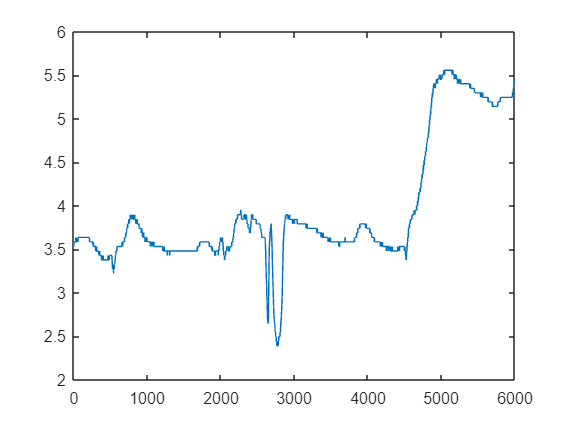


filter1 = Filter1_GSR;
y1 = filter(filter1,GSR_corrected);
filter2 = Filter2_GSR;
y2 = filter(filter2,y1);
plot(GSR_corrected)

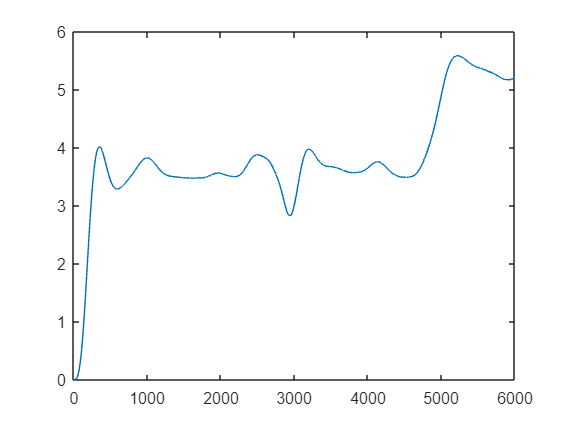

plot(y1)

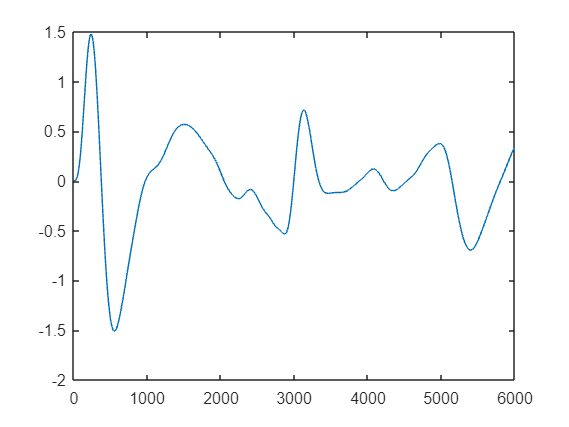

plot(y2)


fprintf('Nilai minimum setelah offset correction: %.2f μS\n', min(y2));

Nilai minimum setelah offset correction: -1.51 μS



%sample = uint32([1:size(y2)]);

num = 0;
onset = zeros(1,1);
offset = zeros(1,1);
peaks = zeros(1,1);

onset_flag = 0;
offset_flag = 0;
onset_val = 0;
offset_val = 0;
onset_idx = 0;
offset_idx = 0;
row_data = size(y2,1)

row_data = 6000

for i=1:row_data-1
    if (y2(i+1,1) - y2(i,1)) > 0  && y2(i,1) > 0.001 && onset_flag == 0
        onset_idx = i;
        onset_val = y2(i,1);
        onset_flag = 1;
        continue;
    end

    if (y2(i+1,1) - y2(i,1)) < 0 && y2(i,1) < 0 && offset_flag == 0 && onset_flag == 1
        offset_idx = i;
        offset_val = y2(i,1);
        onset_flag = 1;
    
        [pks,locs] = findpeaks(y2(onset_idx:offset_idx,1));
        if pks - onset_val > 0.03
            num = num+1;
            onset_flag = 0;
            offset_flag = 0;
            onset(num,1) = onset_val;
            onset(num,2) = onset_idx;
            offset(num,1) = offset_val;
            offset(num,2) = offset_idx;
            peaks(num,1) = pks;
            peaks(num,2) = onset_idx+locs-1;
        end
    end
end

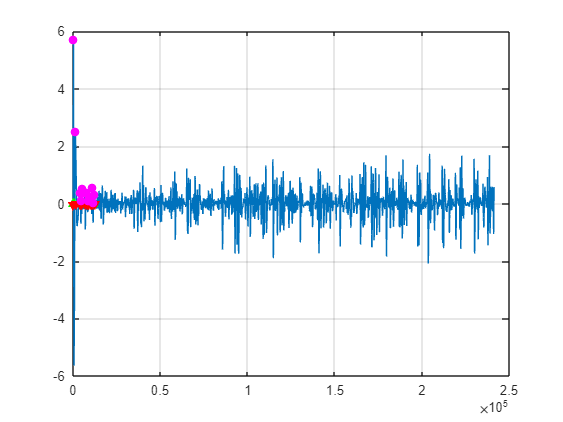

figure
plot(y2)
hold on
plot(onset(:,2), onset(:,1), '^g', 'MarkerFaceColor','g')
plot(offset(:,2), offset(:,1), 'vr', 'MarkerFaceColor','r')
plot(peaks(:,2), peaks(:,1), 'om', 'MarkerFaceColor','m')
hold off
grid

% Menampilkan semua nama fitur dan nilainya
featureNames = fieldnames(features);
disp('Fitur-fitur yang telah diekstraksi:');

Fitur-fitur yang telah diekstraksi:


for i = 1:length(featureNames)
    fname = featureNames{i};
    fvalue = features.(fname);
    if isnan(fvalue)
        fprintf('%s: NaN\n', fname);
    else
        fprintf('%s: %.4f\n', fname, fvalue);
    end
end

SCL_Mean: 15.3825
SCL_STD: 1.4595
SCL_Skewness: -5.0933
SCL_Kurtosis: 50.2091
SCR_Number: 7.0000
SCR_Amplitude_Mean: 1.9023
SCR_Amplitude_STD: 3.9426
SCR_Amplitude_Max: 10.8283
SCR_Amplitude_Min: 0.0760
SCR_Duration_Mean: 3.6457
SCR_Duration_STD: 2.9266
SCR_Duration_Max: 9.1400
SCR_Duration_Min: 0.8400
SCR_Frequency: 1.3956
SCL_Variance: 2.1300
SCL_Slope: 0.0071
GSR_Mean: 15.3825
GSR_STD: 1.4595
GSR_Skewness: -5.0933
GSR_Kurtosis: 50.2091
GSR_Max: 18.8369
GSR_Min: 0.0013
Power_VLF: 1.8784
Power_LF: 1.4415
Power_HF: 0.7434
LF_HF_Ratio: 1.9391
GSR_Trend_Slope: 0.0071



% Atau, menyimpan fitur dalam tabel untuk analisis lebih lanjut
featureTable = struct2table(features);
disp('Tabel Fitur GSR:');

Tabel Fitur GSR:


disp(featureTable);

    SCL_Mean    SCL_STD    SCL_Skewness    SCL_Kurtosis    SCR_Number    SCR_Amplitude_Mean    SCR_Amplitude_STD    SCR_Amplitude_Max    SCR_Amplitude_Min    SCR_Duration_Mean    SCR_Duration_STD    SCR_Duration_Max    SCR_Duration_Min    SCR_Frequency    SCL_Variance    SCL_Slope    GSR_Mean    GSR_STD    GSR_Skewness    GSR_Kurtosis    GSR_Max     GSR_Min     Power_VLF    Power_LF    Power_HF    LF_HF_Ratio    GSR_Trend_Slope
    ________    _______    ____________    _______


% Menyimpan fitur ke file Excel (.xlsx)
excelFileName = 'GSR_Features.xlsx'; % Nama file Excel yang diinginkan
writetable(featureTable, excelFileName, 'Sheet', 'Fitur_GSR');

fprintf('Fitur telah disimpan ke file Excel: %s\n', excelFileName);

Fitur telah disimpan ke file Excel: GSR_Features.xlsx


%Filter untuk Preprocessing

function Hd = Filter1_GSR
%FILTER1_GSR Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.13 and Signal Processing Toolbox 9.1.
% Generated on: 09-Oct-2024 23:25:04

% Chebyshev Type II Lowpass filter designed using FDESIGN.LOWPASS.

% All frequency values are in Hz.
    Fs = 100;  % Sampling Frequency
    
    N     = 4;    % Order
    Fstop = 1.5;  % Stopband Frequency
    Astop = 80;   % Stopband Attenuation (dB)
    
    % Construct an FDESIGN object and call its CHEBY2 method.
    h  = fdesign.lowpass('N,Fst,Ast', N, Fstop, Astop, Fs);
    Hd = design(h, 'cheby2');

% [EOF]
end


function Hd = Filter2_GSR
    %FILTER2_GSR Returns a discrete-time filter object.
    
    % MATLAB Code
    % Generated by MATLAB(R) 9.13 and Signal Processing Toolbox 9.1.
    % Generated on: 10-Oct-2024 00:36:19
    
    % Butterworth Highpass filter designed using FDESIGN.HIGHPASS.
    
    % All frequency values are in Hz.
    Fs = 100;  % Sampling Frequency
    
    N  = 4;     % Order
    Fc = 0.05;  % Cutoff Frequency
    
    % Construct an FDESIGN object and call its BUTTER method.
    h  = fdesign.highpass('N,F3dB', N, Fc, Fs);
    Hd = design(h, 'butter');

% [EOF]
end
